**EPFL Spacecraft Team - CHESS Mission Design**

Arnaud Muller & Antoine Clout

Autumn 2020

clc
clear
close all

Read TUDAT propagation results

if (~exist('PropagationResults')) %#ok<*EXIST>
    PropagationResults= importdata('PropagationResults.dat');
end
Epochs=PropagationResults(:,1);
CartesianPos_C1= PropagationResults(:,2:4);
SRP_C1=PropagationResults(:,5);
CartesianPos_C2= PropagationResults(:,6:8);
SRP_C2= PropagationResults(:,9);

UTC_DateTime=epochToDate(Epochs);
Time=Epochs-Epochs(1);

X1=CartesianPos_C1(:,1);
Y1=CartesianPos_C1(:,2);
Z1=CartesianPos_C1(:,3);
X2=CartesianPos_C2(:,1);
Y2=CartesianPos_C2(:,2);
Z2=CartesianPos_C2(:,3);

Plot trajectories

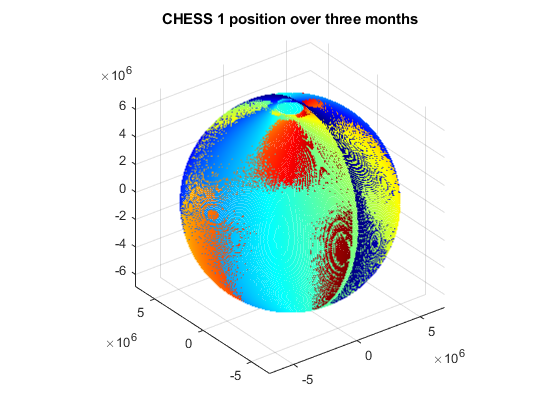

segColors = jet(length(X1)); % Choose a colormap
figure
scatter3(X1,Y1,Z1,1,segColors);
axis equal
title('CHESS 1 position over three months')

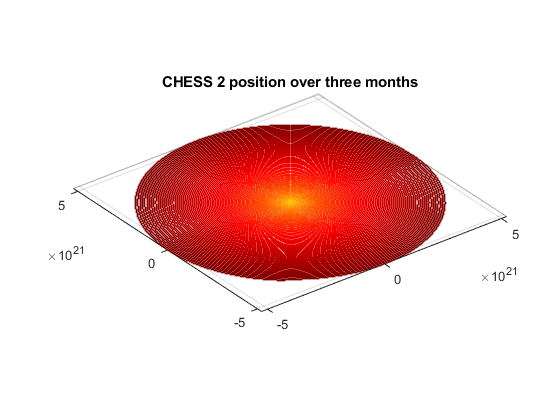



figure
scatter3(X2,Y2,Z2,1,segColors);
axis equal
title('CHESS 2 position over three months')


Rearth=6378136; %Radius Earth in m

Altitude_C1=sqrt(X1.^2+Y1.^2+Z1.^2);
Altitude_C2=sqrt(X2.^2+Y2.^2+Z2.^2);
SMA_C2 = 6928136,

SMA_C2 = 6928136

Ecc_C2 = 0.0424,

Ecc_C2 = 0.0424

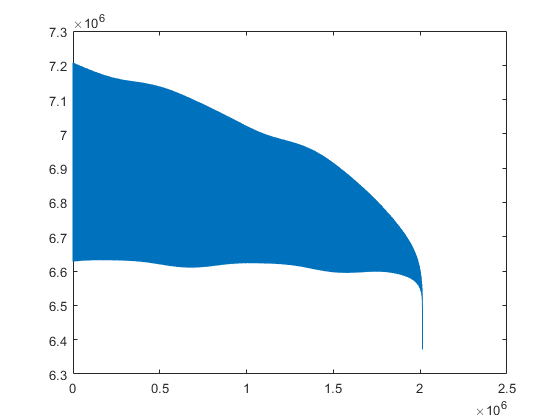


figure
plot(Altitude_C2(Altitude_C2<=SMA_C2*(1+Ecc_C2))-Rearth)